# **1. **`研究人口数据的插值与预测`

`    实验内容：下表给出了从`1940`年到`1990`年的美国人口，`

Pop=[1940:10:1990;...
    132165,151326,179323,203302,226542,249633]

Pop =         1940        1950        1960        1970        1980        1990
      132165      151326      179323      203302      226542      249633


`用插值方法推测`1930`年、`1965`年、`2010`年人口的近似值。`1930`年美国的人口大约是`123,203`千人，你认为你得到的`1965`年和`2010`年的人口数字精确度如何？`

实验代码：

    (1)使用分段插值估计1965年的人口数量

x0=Pop(1,:);
y0=Pop(2,:);
x1965=1965;
px1965=(x1965-x0(4))/(x0(3)-x0(4))*y0(3)+...
       (x1965-x0(3))/(x0(4)-x0(3))*y0(4)

px1965 =      1.913125000000000e+05


    (2)拉格朗日插值估计1930和2010

%1930%
y1930a=Lagrange(x0(1:3),y0(1:3),1930)%只取三个点

y1930a =       121840


yp1=Lagrange(x0(1:3),y0(1:3),1920:1:1960);
plot(1920:1:1960,yp1)
xlabel("只取三个点")


y1930b=Lagrange(x0,y0,1930)%取所有点

y1930b =       169649


yp2=Lagrange(x0,y0,1920:1:1960);
plot(1920:1:1960,yp2)
xlabel("取所有点")

%2010%
y2010a=Lagrange(x0(4:6),y0(4:6),2010)%只取三个点

y2010a =       295368


yp3=Lagrange(x0(4:6),y0(4:6),1980:1:2020);
plot(1980:1:2020,yp3)
xlabel("只取三个点")

y2010b=Lagrange(x0,y0,2010)%取所有点

y2010b =       171351


yp4=Lagrange(x0,y0,1980:1:2020);
plot(1980:1:2020,yp4)
xlabel("取所有点")

结论：只取三点的情况下较为精确，误差较小

# **2**`．最小二乘法拟合经验公式`

`    实验内容：某类疾病发病率为``‰和年龄段`(`每五年为一段，例如`0~5`岁为第一段，`6~10`岁为第二段`……)`之间有形如``的经验关系，观测得到的数据表如下`

ta=[1:19;...
    0.898 2.38 3.07 1.84 2.02... 
    1.94 2.22 2.77 4.02 4.76 ...
    5.46 6.53 10.9 16.5 22.5 ...
    35.7 50.6 61.6 81.8];

`    （`1`）用最小二乘法确定模型``中的参数a和b。`

`    （`2`）利用`MATLAB`画出离散数据及拟合函数``图形。`

`  解`

`            由题意设  `$y={\textrm{ae}}^{\textrm{bx}}$

                                          
$$\textrm{lny}=\textrm{bx}+\textrm{lna}$$


                        正规方程为AM+N=O                                          

xk=ta(1,:);
fk=ta(2,:);
M=[length(xk),sum(xk);sum(xk),sum(xk.^2)];

Index exceeds the number of array elements (1).

O=[sum(log(fk)),sum(xk.*log(fk))];
Solution=(O/M)';
lna=Solution(1);
a=exp(lna)
b=Solution(2)
plot(xk,exp(lna)*exp(b*xk),"-o","MarkerSize",5 ,"MarkerFaceColor","auto")
xlabel("年龄/岁")
ylabel("发病率/‰")
str=['y=',num2str(exp(lna)),'exp(',num2str(b),'x)'];
text(6,40,str,'FontSize',15)

# `3.` `复化求积公式`

`    实验内容：对于定积分``。`

`        （``1``）分别取n=2,3...10利用复化梯形公式计算，并与真值比较。再画出计算误差与n之间的曲线。     `

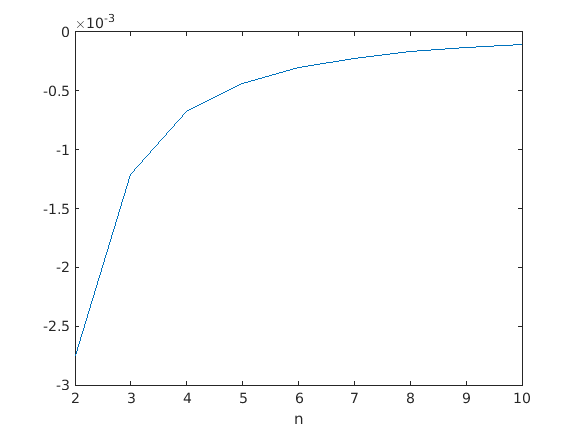

t=zeros(1,9);
for count=1:9
    t(count)=Trapezia(0,1,count+1,'func_ts');
end
err=t-0.5*(log(5)-log(4)).*ones;
plot(2:10,err)
xlabel("n")

ylabel("error")

Unrecognized function or variable 'pylabel'.

`        （`2`）取`[0`，`1]`上的`9`个点，分别用复化梯形公式和复化辛普森公式计算，并比较精度。`

 t8=Trapezia(0,1,8,'func_ts')
 s4=Simpson(0,1,4,'func_ts')
 errsim=s4-0.5*(log(5)-log(4)).*ones
 errtra=t8-0.5*(log(5)-log(4)).*ones
 